warning('off','all')
clear
%%%% required parameters
envSize_X = 10;
envSize_Y = 10;
initialRobotsPositions = [1 1.1; 2 1 ;2.5 1; 2 2; 3 1;1 3;1.5 4;2 3];
initialRobotsPositions = rand(6,2)*envSize_Y        

initialRobotsPositions =     6.8921    1.5238
    7.4815    8.2582
    4.5054    5.3834
    0.8382    9.9613
    2.2898    0.7818
    9.1334    4.4268


res = 0.1;
res = 1/res;
display = 1;
iterations = 50;
k = 1;
alpha = 1;
health = [1 1 1 0.1 1 1 ];
wts = [1 1 1 1 1 1];
loctaionalCostCell = cell(1,1);
initialRobotsEnergy = [50 100 100 100 100 100];
currentRobotsEnergy = initialRobotsEnergy;
robotsAlpha =[ 1 8 1 1 1 1];
robotsBeta = [ 4 8 4 4 4 4];
areaAssigned = [];
velocity  = [0.5 0.5 0.5 0.5 0.5 0.5];
filePath = append('/home/aimanmunir/Desktop/CoverageControlResults/AdaptiveTrust/envSize',num2str(envSize_Y),'/')

filePath = '/home/aimanmunir/Desktop/CoverageControlResults/AdaptiveTrust/envSize10/'

color = ["red","green","black","blue","yellow","cyan","magenta","#D95319"];

areaArray = cell(size(initialRobotsPositions,1),1);                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 
energyArray = cell(size(initialRobotsPositions,1),1);
distToCentroidCell = cell( size(initialRobotsPositions,1),1);
cumulativeDistance = zeros(size(initialRobotsPositions,1),1);
cumulativeDistValues = cell( size(initialRobotsPositions,1),1);

% Initial Voronoi 
% find its centroid
%%%%%%%%% For iterations
% show voronoi 
% getBoundary, Neighbors , Centroid, Mass
% Update weights
%%%%%%%%%%%%%%%%%%%%%% Conference Paper Eq 10 %%%%%%%%%%%%%%%%%%%%%
positionArray = cell(iterations+1,1);
r = transpose(initialRobotsPositions);
currentRobotPositions = initialRobotsPositions;
positionArray{1} = [positionArray{1};initialRobotsPositions];
[X,locations,locationIdxs,cellBoundaries,areaAssigned] = partitionFinder(filePath,currentRobotPositions,envSize_X, envSize_Y, wts,res,0, 'Initial voronoi partition',positionArray);

iter = 'Initial voronoi partition'

iter = '1'

iter = '2'

iter = '3'

iter = '4'

iter = '5'

iter = '6'

iter = '7'

iter = '8'

iter = '9'

iter = '10'

iter = '11'

iter = '12'

iter = '13'

iter = '14'

iter = '15'

iter = '16'

iter = '17'

iter = '18'

iter = '19'

iter = '20'

iter = '21'

iter = '22'

iter = '23'

iter = '24'

iter = '25'

iter = '26'

iter = '27'

iter = '28'

iter = '29'

iter = '30'

iter = '31'

iter = '32'

iter = '33'

iter = '34'

iter = '35'

iter = '36'

iter = '37'

iter = '38'

iter = '39'

iter = '40'

iter = '41'

iter = '42'

iter = '43'

iter = '44'

iter = '45'

iter = '46'

iter = '47'

iter = '48'

iter = '49'

iter = '50'

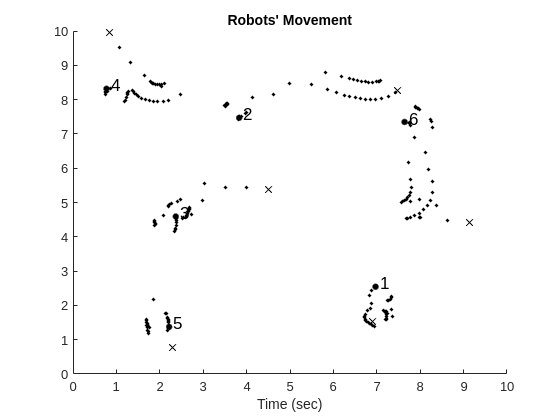

[C_x, C_y, locationalCost] = getCentroidForManualVoronoi_withCost(locations,1,initialRobotsPositions,wts);
Mass = areaAssigned;
density = getDensityValues_ManualVoronoi(X,0);
updatedWeights = transpose(wts);
iter = cell(1,1);
diffValues = cell( size(initialRobotsPositions,1),1);
weightValues = cell( size(initialRobotsPositions,1),1);
distValues = cell( size(initialRobotsPositions,1),1);
for i= 1:iterations
    % Updated robots positions CX Cy
    if(i>15)
        robotsAlpha(1) = 8;
    end
    robotsPositions_center = [C_x,C_y];
    robotsPositions_diff = ( robotsPositions_center-currentRobotPositions);
    loctaionalCostCell{1} =[loctaionalCostCell{1},locationalCost];
    for r = 1:size(currentRobotPositions,1)
        distanceCV= sqrt(( currentRobotPositions(r,1)-C_x(r) )^2 + (currentRobotPositions(r,2)-C_y(r))^2) ;
        distToCentroidCell{r} = [distToCentroidCell{r},[abs(distanceCV)]];
        areaArray{r} = [areaArray{r};areaAssigned(r,:)];
        dist = 1+ distanceCV ;
        u_ix = velocity(1)*(robotsPositions_diff(r,1)/abs(distanceCV));
        u_iy = velocity(1)*(robotsPositions_diff(r,2)/abs(distanceCV));
        KVALUES(r) = 1/dist;
        positionAtLastTimeStep = currentRobotPositions(r,:);
        if(~isnan(u_ix))
            currentRobotPositions(r,1) = currentRobotPositions(r,1)+u_ix;
        else
            currentRobotPositions(r,1) = currentRobotPositions(r,1);
        end
        if(~isnan(u_iy))
            currentRobotPositions(r,2) = currentRobotPositions(r,2)+u_iy;
        else
            currentRobotPositions(r,2) = currentRobotPositions(r,2);
        end
        
        distanceTravelled =   (( positionAtLastTimeStep(1)- currentRobotPositions(r,1) )^2 + (positionAtLastTimeStep(2)- currentRobotPositions(r,2))^2); 
        cumulativeDistance(r) = cumulativeDistance(r) + distanceTravelled;
        cumulativeDistValues{r} = [cumulativeDistValues{r},[cumulativeDistance(r)]];
        energyAtLastTimeStep = currentRobotsEnergy(r);
        energySpent = getRobotEnergy(currentRobotsEnergy(r),distanceTravelled,robotsAlpha(r),robotsBeta(r)); 
        currentRobotsEnergy(r) =  ( energyAtLastTimeStep - energySpent);
    end
    positionArray{i+1} = [positionArray{i+1};currentRobotPositions(:,1),currentRobotPositions(:,2)];
    if(i~=iterations)
        [X,locations,locationIdxs,cellBoundaries,areaAssigned] = partitionFinder(filePath,currentRobotPositions,envSize_X, envSize_Y, updatedWeights ,res,0,num2str(i),positionArray);
    else
        [X,locations,locationIdxs,cellBoundaries,areaAssigned] = partitionFinder(filePath,currentRobotPositions,envSize_X, envSize_Y, updatedWeights ,res,1,num2str(i),positionArray);
    end

    [neighborsInfo,neighborsSharedBoundary,neighborsCount] = getNeighborsInformation_manualVoro(cellBoundaries);
    neighborsSharedBoundary;
    [C_x, C_y,locationalCost ] = getCentroidForManualVoronoi_withCost(locations,1, currentRobotPositions,updatedWeights);
    lastWeights = updatedWeights;
    Mass = areaAssigned;
    updatedWeights = UpdateWeights_eq10_energyVersion(cellBoundaries,density,neighborsCount,neighborsSharedBoundary,currentRobotPositions,lastWeights,initialRobotsPositions(:,1),initialRobotsPositions(:,2),Mass,KVALUES , alpha);
    updatedWeights = lastWeights + updatedWeights;
    diff = updatedWeights - transpose(currentRobotsEnergy);
    iter{1} = [iter{1},i];
    for r = 1:size(initialRobotsPositions,1)
        diffValues{r} = [diffValues{r},[diff(r,:)]];
        weightValues{r} = [weightValues{r},[updatedWeights(r,:)]];
    end
end


updatedWeights

updatedWeights =     4.0774
    0.8895
   -0.8349
   -1.8918
   -1.0548
    4.8424


areaAssigned

areaAssigned =    27.9350
   14.2000
   12.7300
    7.3300
   12.2650
   24.6700


hold off;

figure;
for values = 1:size(initialRobotsPositions,1)
    diffValues{values}
    plot(iter{1},diffValues{values},Color="black");
    hold on;
end

ans =   -46.6038  -44.2297  -41.9478  -39.8100  -37.5788  -35.4973  -33.2883  -31.2330  -29.0944  -27.0768  -24.9716  -22.9780  -20.8907  -18.9149  -16.8375   -7.8692    1.2067   10.1654   19.2324   28.1947   37.2625   46.2272   55.2959   64.2589   73.3228   82.3023   91.3768  100.3686  109.4653  118.4479  127.5330  136.5319  145.6382  154.6516  163.7418  172.7440  181.8460  190.8537  199.9261  208.9204  217.9812  226.9670  236.0213  245.0031  254.0540  263.0327  272.0786  281.0543  290.1017  299.0774


ans =   -88.6759  -78.2981  -68.0430  -58.0049  -47.8134  -37.5667  -27.4245  -17.2655   -7.1863    2.8976   12.9368   22.9323   32.9534   42.9784   52.9781   62.9756   73.0111   82.9721   92.9431  102.9023  112.8723  122.8404  132.8649  142.7722  152.7193  162.6257  172.5261  182.4034  192.1742  201.9871  211.7546  221.5310  231.2762  241.2332  250.9917  261.0831  270.9830  280.9759  290.8199  300.9277  310.7972  320.9120  330.7948  340.9036  350.7934  360.9006  370.7949  380.8926  390.7936  400.8895


ans =   -97.0367  -95.1754  -93.4468  -91.7559  -90.0842  -88.2595  -86.4476  -84.5923  -82.7514  -80.8243  -78.9501  -76.9597  -75.0380  -73.0169  -71.1016  -69.0560  -67.1264  -65.0713  -63.1482  -61.0803  -59.1449  -57.0780  -55.1425  -53.0698  -51.1234  -49.0466  -47.0931  -45.0081  -43.0178  -40.8515  -38.9524  -36.8414  -34.8983  -32.8430  -30.9108  -28.8809  -26.9346  -24.8416  -22.9006  -20.8552  -18.9084  -16.8505  -14.9101  -12.8512  -10.9088   -8.8518   -6.9086   -4.8451   -2.8997   -0.8349


ans =   -97.3621  -95.7024  -93.9984  -92.0456  -90.2768  -88.5391  -86.7102  -84.8913  -83.0071  -81.1323  -79.2210  -77.2591  -75.3469  -73.4404  -71.4995  -69.5673  -67.6148  -65.6540  -63.6978  -61.7252  -59.7644  -57.7937  -55.8246  -53.8033  -51.8307  -49.7954  -47.8045  -45.7526  -43.6990  -41.8286  -39.6469  -37.6692  -35.6557  -33.7818  -31.5827  -29.7659  -27.7428  -25.8606  -23.6787  -21.8460  -19.7018  -17.8803  -15.7250  -13.8952  -11.7367   -9.8963   -7.7382   -5.8927   -3.7361   -1.8918


ans =   -97.3148  -95.6353  -94.0246  -92.2497  -90.5629  -88.7086  -86.9562  -85.0250  -83.1830  -81.2264  -79.3485  -77.3688  -75.4750  -73.4725  -71.5583  -69.5407  -67.6132  -65.5841  -63.6477  -61.6118  -59.6709  -57.6274  -55.6794  -53.6330  -51.6789  -49.6323  -47.6732  -45.6250  -43.6681  -41.5945  -39.6025  -37.4880  -35.4709  -33.3641  -31.3627  -29.2790  -27.3037  -25.2433  -23.2534  -21.1882  -19.2094  -17.1492  -15.1770  -13.1187  -11.1508   -9.0949   -7.1262   -5.0729   -3.1059   -1.0548


ans =   -96.4566  -94.1301  -91.7061  -89.3830  -87.1318  -84.9855  -82.8474  -80.7532  -78.6287  -76.5514  -74.4279  -72.3698  -70.2623  -68.2131  -66.0981  -64.0611  -62.0225  -59.9750  -57.8512  -55.8282  -53.7232  -51.7144  -49.6870  -47.6594  -45.5717  -43.5706  -41.4994  -39.5050  -37.4304  -35.3649  -33.2359  -31.1931  -29.0821  -27.1006  -25.0225  -23.0615  -21.0749  -19.1110  -17.0897  -15.1330  -13.1075  -11.1463   -9.1181   -7.1527   -5.1247   -3.1561   -1.1268    0.8456    2.8679    4.8424


title(" InterRobotTrust -  w_i - e_i")
        initialRobotsPositions

initialRobotsPositions =     6.8921    1.5238
    7.4815    8.2582
    4.5054    5.3834
    0.8382    9.9613
    2.2898    0.7818
    9.1334    4.4268


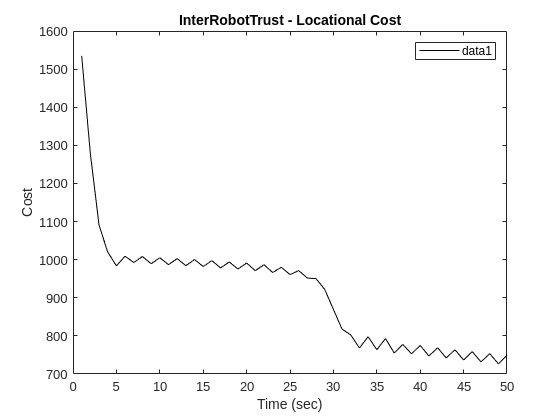

saveas(gcf, fullfile(filePath, "weightEnergyDiff"), 'jpg');
hold off;

figure;
for values = 1:size(initialRobotsPositions,1)
    plot(iter{1},weightValues{values},Color=color(values));
    hold on;
end
title("InterRobotTrust - weights")
saveas(gcf, fullfile(filePath,"Weights" ), 'jpg')

hold off;

figure;
plot(iter{1},loctaionalCostCell{1},Color="black");
legend();
ylabel("Cost")
xlabel("Time (sec)")
title("InterRobotTrust - Locational Cost")
saveas(gcf, fullfile(filePath,"LocationalCost" ), 'jpg')
hold off;

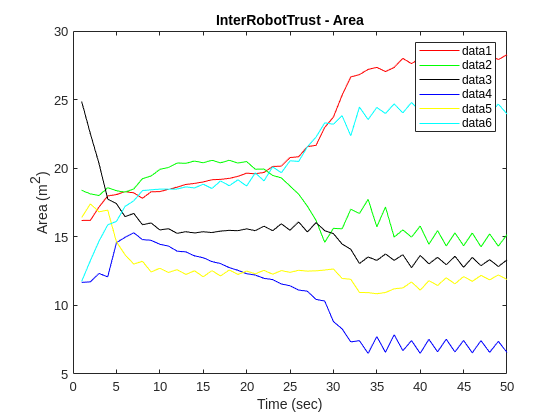

   
figure;
for values = 1:size(weightValues)        
    plot(iter{1},areaArray{values},Color=color(values));
    hold on;
end
legend();
title("InterRobotTrust - Area");
ylabel("Area (m^2)")
xlabel("Time (sec)")
saveas(gcf, fullfile(filePath,"Area" ), 'jpg');
hold off;

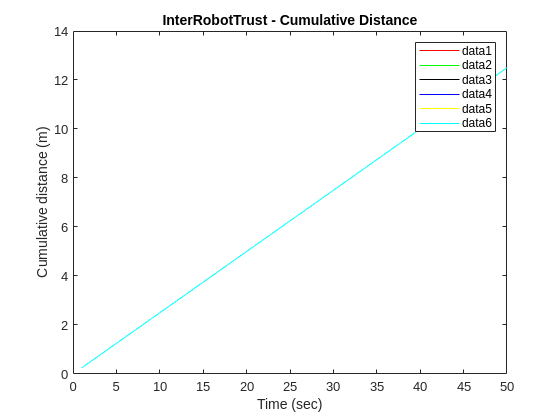

    
figure;
for values = 1:size(weightValues)
    plot(iter{1},cumulativeDistValues{values},Color=color(values));
    hold on;
end
legend();
ylabel("Cumulative distance (m)")
xlabel("Time (sec)")
title("InterRobotTrust - Cumulative Distance")
saveas(gcf, fullfile(filePath,"CumulativeDistance" ), 'jpg');
    hold off;

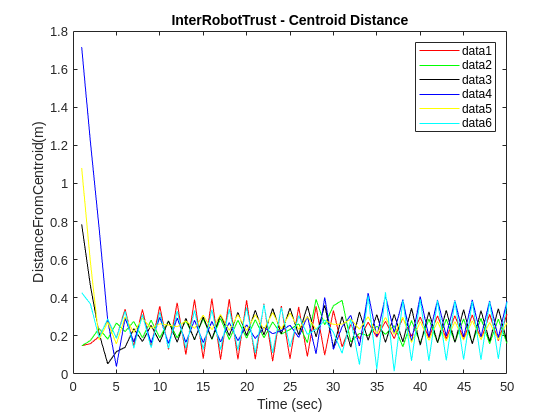


figure;
for values = 1:size(weightValues)
    plot(iter{1},distToCentroidCell{values},Color=color(values));
    hold on;
end
legend();
ylabel("DistanceFromCentroid(m)")
xlabel("Time (sec)")
title("InterRobotTrust - Centroid Distance")
saveas(gcf, fullfile(filePath,"CentroidDistance (C_i - p_i)" ), 'jpg');
    hold off;